clearvars;
files = dir('*sc.mat');
file = 12

file = 12

load(files(file).name)

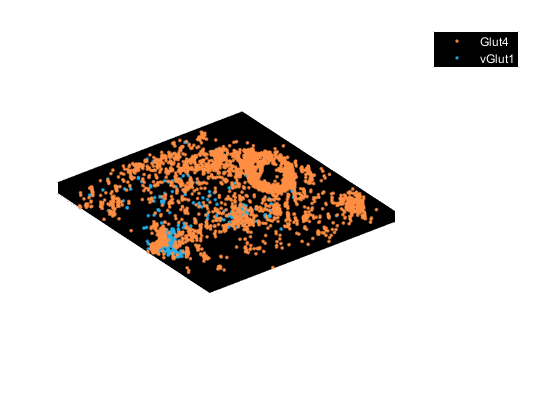

% Create a graph to visualize red and Orange data
ind_r = abs(cdata.red.zf) < 0.5;
ind_o = abs(cdata.orange.zf) < 0.5;
plot3(cdata.red.xf(ind_r),cdata.red.yf(ind_r),cdata.red.zf(ind_r),'.')
hold on
vector = xy_feature(cdata.orange.xf/cal.q,cdata.orange.yf/cal.q);
xf_o = cal.q*cal.o2rx.'*vector.';
yf_o = cal.q*cal.o2ry.'*vector.';
plot3(xf_o(ind_o), yf_o(ind_o),cdata.orange.zf(ind_o),'.')
hold off
axis equal
title('Non-corrected overlayed 3d localization data')
legend('Glut4','vGlut1')

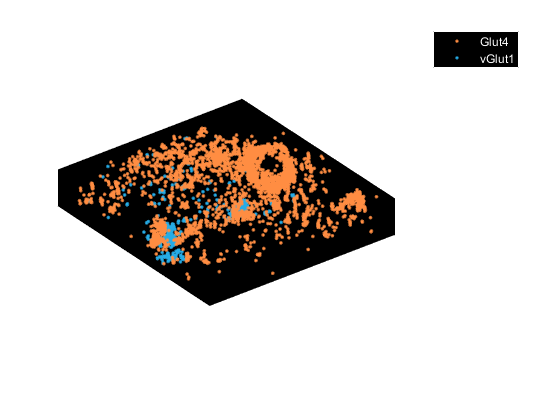

plot3(cdata.red.xf(ind_r),cdata.red.yf(ind_r),cdata.red.zf_raw(ind_r),'.')
hold on
plot3(xf_o(ind_o), yf_o(ind_o),cdata.orange.zf_raw(ind_o),'.')
hold off
axis equal
title('Smoothed corrected overlayed 3d localization data')
legend('Glut4','vGlut1')



    clear M
    view(0,30)
    M = getframe(gcf)
    for i = 1:359
        view(i,30);
        M(numel(M)+1) = getframe(gcf);
    end
    

movie2gif(M,'glut4_surface.gif','DelayTime',0.03,'LoopCount',Inf)